% Use a linearly weighted fitness a1f1 + a2f2 + a3f3 =: fw
% Test the algorithm on minimizing fw
% Use three different choices of the weights
% Graph Size: 15

% a1 + a2 + a3 = 1
% Three choices:
% 1. (a1, a2, a3) = (0.34, 0.33, 0.33)
% 2. (a1, a2, a3) = (0.5, 0.25, 0.25)
% 3. (a1, a2, a3) = (0.25, 0.5, 0.25)

% Choice 1: (a1, a2, a3) = (0.34, 0.33, 0.33)
[bestGraph, fw] = EA_weighted_fitness(15, 0.3, 0.3, 0.34, 0.33, 0.33);
f1 = cal_avg_path_len(bestGraph);
f2 = cal_diameter(bestGraph);
f3 = cal_link_num(bestGraph);
fprintf("Choice 1: " + "(a1, a2, a3) = (0.34, 0.33, 0.33)\n" ...
        + "fw: " + fw + ",  f1: " + f1 + ",  f2: " + f2 + ",  f3: " + f3 + "\n");

Choice 1: (a1, a2, a3) = (0.34, 0.33, 0.33)
fw: 5.9147,  f1: 1.8667,  f2: 2,  f3: 14


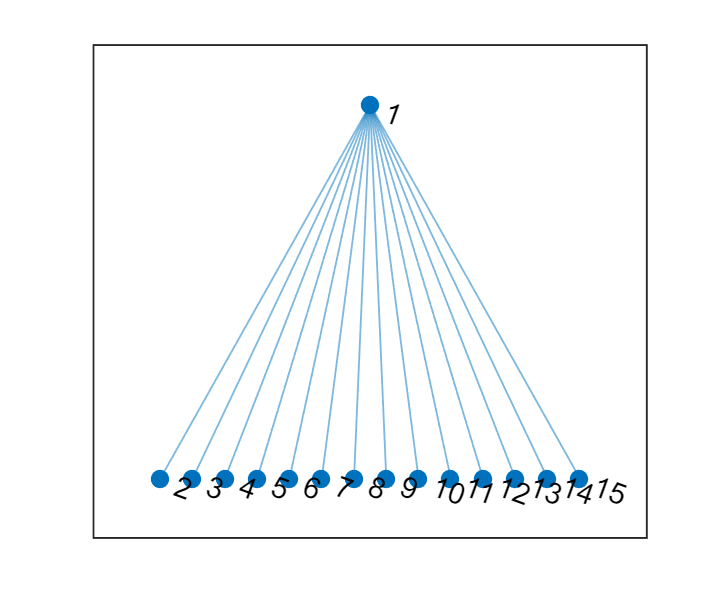

set(gcf,'Position',[100 100 260 220]);
plot(graph(bestGraph));

% Choice 2: (a1, a2, a3) = (0.5, 0.25, 0.25)
[bestGraph, fw] = EA_weighted_fitness(15, 0.3, 0.3, 0.5, 0.25, 0.25);
f1 = cal_avg_path_len(bestGraph);
f2 = cal_diameter(bestGraph);
f3 = cal_link_num(bestGraph);
fprintf("Choice 2: " + "(a1, a2, a3) = (0.5, 0.25, 0.25)\n" ...
        + "fw: " + fw + ",  f1: " + f1 + ",  f2: " + f2 + ",  f3: " + f3 + "\n");

Choice 2: (a1, a2, a3) = (0.5, 0.25, 0.25)
fw: 5.7,  f1: 2.4,  f2: 4,  f3: 14


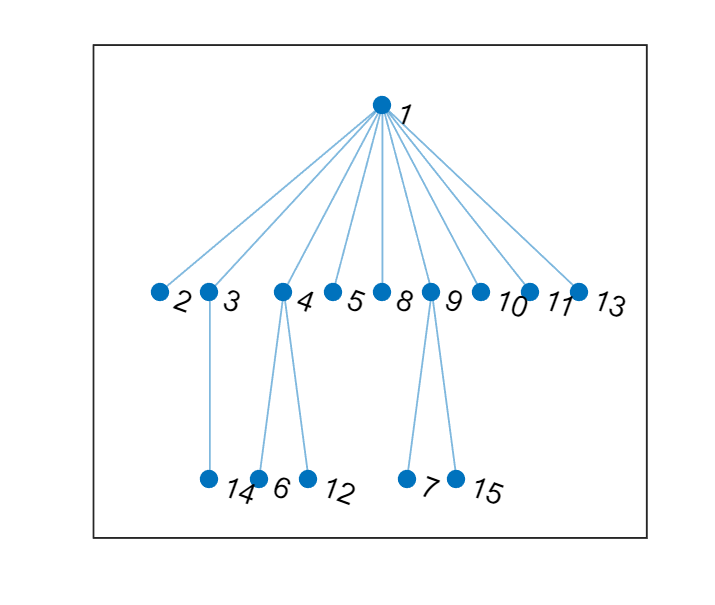

plot(graph(bestGraph));

% Choice 3: (a1, a2, a3) = (0.25, 0.5, 0.25)
[bestGraph, fw] = EA_weighted_fitness(15, 0.3, 0.3, 0.25, 0.5, 0.25);
f1 = cal_avg_path_len(bestGraph);
f2 = cal_diameter(bestGraph);
f3 = cal_link_num(bestGraph);
fprintf("Choice 1: " + "(a1, a2, a3) = (0.25, 0.5, 0.25)\n" ...
        + "fw: " + fw + ",  f1: " + f1 + ",  f2: " + f2 + ",  f3: " + f3 + "\n");

Choice 1: (a1, a2, a3) = (0.25, 0.5, 0.25)
fw: 5.8119,  f1: 2.2476,  f2: 3,  f3: 15


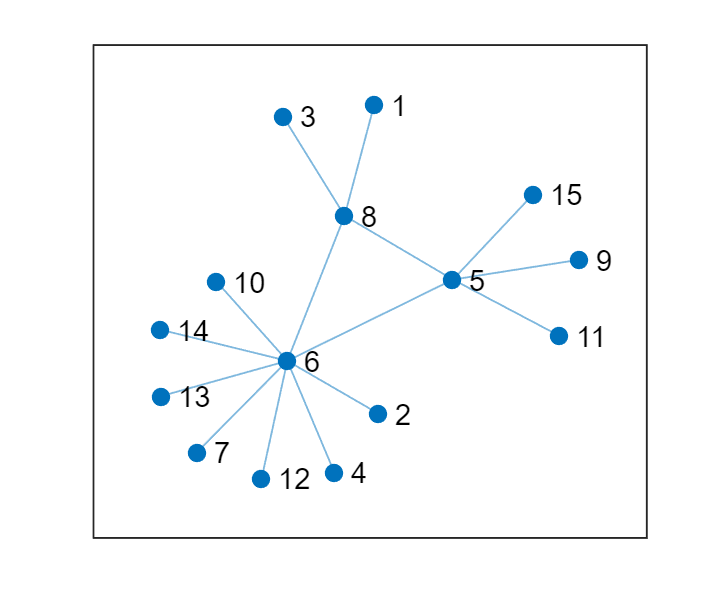

plot(graph(bestGraph));

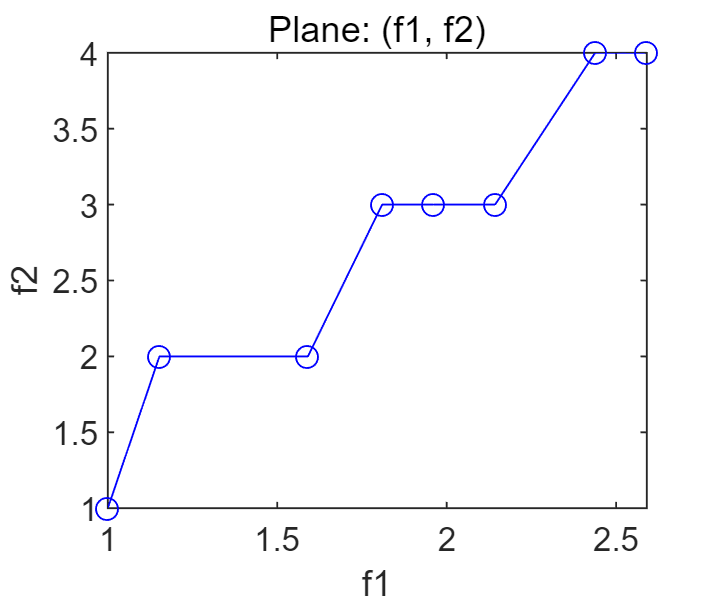

% Multi-Objective Evolutionary Algorithm
% Algorithm: NSGA-II 
% Minimize each of the three costs (f1, f2, f3)
% Return the 10 best solutions with their multi-fitness
[bestSolutions, multiFitValues] = MOEA(15, 0.3, 0.3);

% Calculate the inverse of multi-fitness to achieve the values of f1, f2, f3
f1 = ones(1, 10)./multiFitValues{1};
f2 = ones(1, 10)./multiFitValues{2};
f3 = ones(1, 10)./multiFitValues{3};

% Display the 10 best solutions, projected on the (f1, f2), (f1, f3), (f2, f3)
% Plane: (f1, f2)
set(gcf,'Position',[100 100 260 220]);
% Sort the values for connecting points into a line
[sortF1, sortIndexes] = sort(f1);
plot(sortF1, f2(sortIndexes), 'b-o');
title("Plane: (f1, f2)")
xlabel("f1")
ylabel("f2")

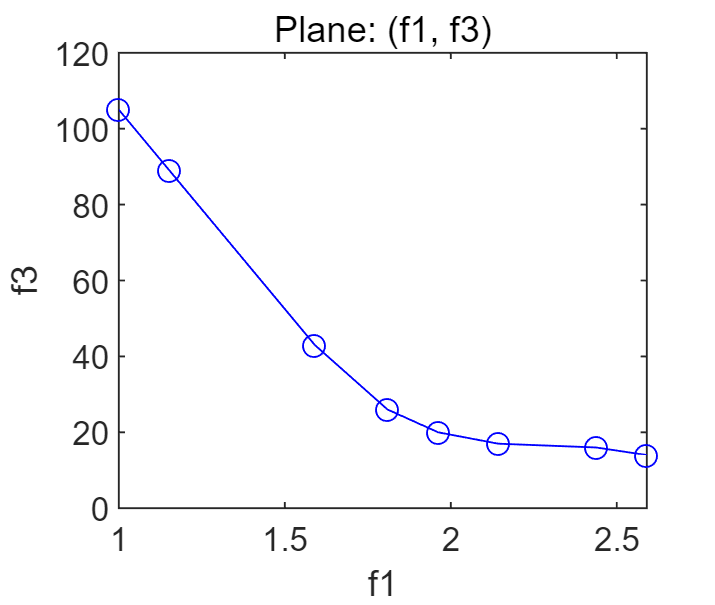

% Plane: (f1, f3)
[sortF1, sortIndexes] = sort(f1);
plot(sortF1, f3(sortIndexes), 'b-o');
title("Plane: (f1, f3)")
xlabel("f1")
ylabel("f3")

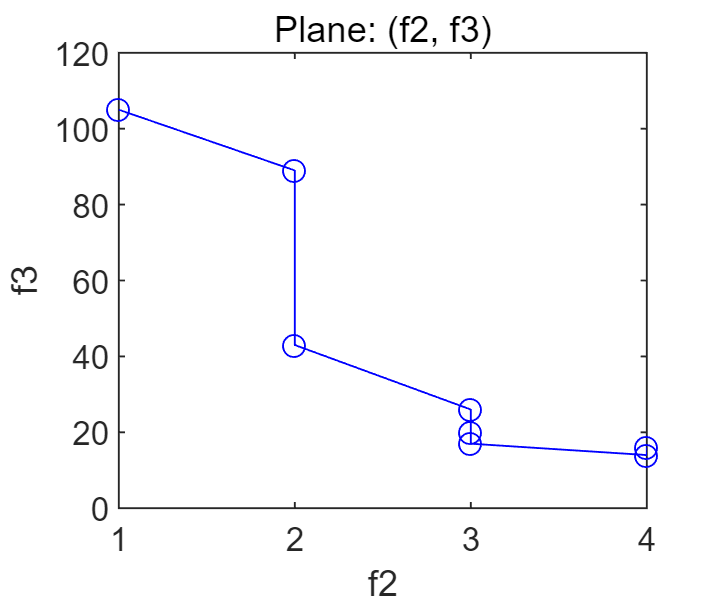

% Plane: (f2, f3)
[sortF2, sortIndexes] = sort(f2);
plot(sortF2, f3(sortIndexes), 'b-o');
title("Plane: (f2, f3)")
xlabel("f2")
ylabel("f3")

% List the table of f1, f2, f3 values of the 10 best solutions
for i = 1 : 10
    if i == 1
        fprintf("     f1        f2        f3")
    end
    fprintf("" + i + ": " + "%.4f,   %.4f,   %.4f\n", f1(i), f2(i), f3(i));
end

     f1        f2        f3

1: 1.0000,   1.0000,   105.0000
2: 2.5905,   4.0000,   14.0000
3: 1.0000,   1.0000,   105.0000
4: 2.5905,   4.0000,   14.0000
5: 1.1524,   2.0000,   89.0000
6: 1.8095,   3.0000,   26.0000
7: 1.5905,   2.0000,   43.0000
8: 1.9619,   3.0000,   20.0000
9: 2.4381,   4.0000,   16.0000
10: 2.1429,   3.0000,   17.0000
